# Attitude Controller Check

Jérémie Xavier Joseph Bannwarth, 28/03/2017

## Summary

Check how the attitude controller works.

## Controller inputs

Use arbitrary values.

thrust_sp = 0.5;
q_sp  = EulerToQuat( deg2rad( [30, -10, 0] ) );
q_att = EulerToQuat( deg2rad( [0, 0, 0] ) );
R_sp  = QuatToRot( q_sp );
R     = QuatToRot( q_att );

## Find shortest path to target

R_z = R(:,3);
R_sp_z = R_sp(:,3);

Visualize matrices up to this point

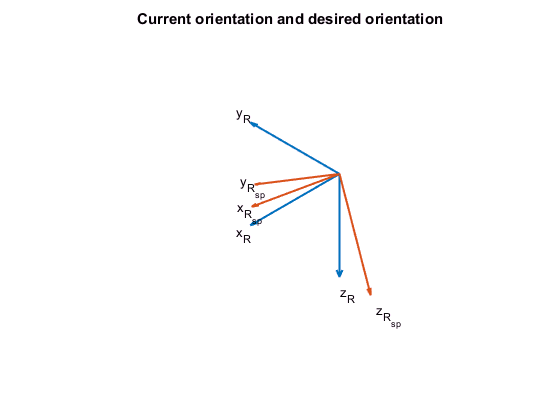

figure('Name', 'Rotation matrices');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title('Current orientation and desired orientation')
cmap = get(gca,'colororder');
h(1:3) = PlotReferenceFrame( R,    1, 'R',      cmap(1,:) );
h(4:6) = PlotReferenceFrame( R_sp, 1, 'R_{sp}', cmap(2,:) );
view([1 1 1])
% legend(h(3:4), {'cur' 'sp'});
set(findobj(gcf, 'type', 'axes'), 'Visible', 'off') % Clean up graph
set(findall(gca, 'type', 'text'), 'Visible', 'on');

Simply look at $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$:

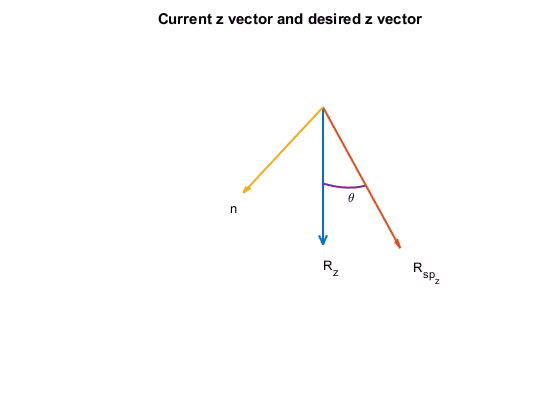

figure('Name', 'Rotation matrices');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title('Current z vector and desired z vector')
cmap = get(gca,'colororder');
PlotVector( R_z, 1, 'R_z', cmap(1,:) )
PlotVector( R_sp_z, 1, 'R_{sp_z}', cmap(2,:) )
PlotVector( cross(R_z, R_sp_z)./norm(cross(R_z, R_sp_z)), 1, 'n', cmap(3,:) )
PlotArc( R, R_sp_z, 0.5, '\theta', cmap(4,:) )
view([1 1 1])
set(findobj(gcf, 'type','axes'), 'Visible', 'off') % Clean up graph
set(findall(gca, 'type', 'text'), 'Visible', 'on');

We want to rotate from $\mathbf{R}_z$ to $\mathbf{R}_{ \mathrm{sp}_z }$ in the shortest path. The rotation required to go from $\mathbf{R}_z$ to $\mathbf{R}_{ \mathrm{sp}_z }$, or error, can be expressed in axis angle form as the rotation $\theta$ around the unit-length vector $\mathbf{n}$, which is normal to $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$.

Since $|\mathbf{R}| = |\mathbf{R}_{\mathrm{sp}_z}| = 1$, we can use the properties of the cross and dot products to find $\theta$ and $\mathbf{n}$:


$$\mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} = |\mathbf{R}_z| |\mathbf{R}_{\mathrm{sp}_z}|\mathbf{n} \, {\sin\theta}
\rightarrow \sin\theta = \left|\mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z}\right|, \; \mathbf{n} = \mathbf{R}^\top \frac{1}{\sin\theta} \left( \mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} \right)$$



$$\mathbf{R} \cdot \mathbf{R}_{\mathrm{sp}_z} = |\mathbf{R}|\cos\theta \rightarrow
\cos\theta = \mathbf{R} \cdot \mathbf{R}_{\mathrm{sp}_z}$$



$$\theta = \arctan\left( \frac{ | \mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} | }{  \mathbf{R}_z \cdot \mathbf{R}_{\mathrm{sp}_z} \right)$$


$\theta$ and $\mathbf{n}$ can be combined as a single vector $\mathbf{e}_R$:


$$\mathbf{e}_R = \theta \mathbf{n}$$


e_R = R' * cross(R_z, R_sp_z);             % sin theta * n
e_R_z_sin = norm(e_R);                     % sin theta
e_R_z_cos = dot(R_z, R_sp_z);              % cos theta
e_R_z_angle = atan2(e_R_z_sin, e_R_z_cos); % theta
e_R_z_axis = e_R ./ e_R_z_sin;             % n

e_R = e_R_z_axis .* e_R_z_angle;           % e_R

The cross product between two vectors $\mathbf{a}$ and $\mathbf{b}$ can also be expressed as a matrix multiplication:


$$\mathbf{a} \times \mathbf{b} = \mathbf{A} \mathbf{b}, \; \mathrm{where} \; \mathbf{A} =
\pmatrix{0 & -a_3 & a_2 \cr
a_3 & 0 & -a_1 \cr
-a_2 & a_1 & 0}$$


A rotation matrix representing the rotation $\mathbf{e}_R$ can be obtained by the following equation:


$$\mathbf{R}_\text{rp} = \mathbf{R} \left(
\mathbf{I}
+
\mathbf{E}_R \sin\theta
+
{\mathbf{E}_R}^2 \left( 1 - \cos\theta \right)
\right)$$


where $\mathbf{E}_R$ is the cross-product matrix form of $\mathbf{e}_R$. Full derivation for this equation can be found at:

S. van Der Walt, *The 3 x 3 rotation matrix. *Available: [http://dip.sun.ac.za/~stefan/TWB264/notas/engels/12_rot_3x3_eng.pdf](http://dip.sun.ac.za/~stefan/TWB264/notas/engels/12_rot_3x3_eng.pdf)

% Cross product matrix for e_R_axis
e_R_cp = zeros(3,3); % E_R
e_R_cp(1, 2) = -e_R_z_axis(3);
e_R_cp(1, 3) =  e_R_z_axis(2);
e_R_cp(2, 1) =  e_R_z_axis(3);
e_R_cp(2, 3) = -e_R_z_axis(1);
e_R_cp(3, 1) = -e_R_z_axis(2);
e_R_cp(3, 2) =  e_R_z_axis(1);

% Rotation matrix for roll/pitch only rotation
R_rp = R * ( eye(3,3) + e_R_cp * e_R_z_sin + e_R_cp * e_R_cp * (1.0 - e_R_z_cos) );